We extract FRC of a three DOFs model with 1:1:1 internal resonance


$$\ddot{x}_1+x_1+\epsilon c_1\dot{x}_1+ K(x-y)^3=\epsilon f_1\cos\Omega t,\\
\ddot{x}_2+x_2+\epsilon c_2\dot{x}_2+ K[(y-x)^3+(y-z)^3]=\epsilon f_2\cos\Omega t,\\
\ddot{x}_3+x_3+\epsilon c_3\dot{x}_3+ K(z-y)^3=\epsilon f_3\cos\Omega t.$$


clear all, close all, clc

## Example Setup

c1 = 1e-1;
c2 = 2e-1;
c3 = 3e-1;
K = 0.2; 
epsilon = 5e-3;
[mass,damp,stiff,fnl,fext]=build_model(c1,c2,c3,K,epsilon);

## Dynamical System Setup

DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

% Forcing
kappas = [1; -1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

**Linear Modal analysis**

startMD = tic;
[V,D,W] = DS.linear_spectral_analysis();


 The first 6 eigenvalues are given as 
  -0.0002 + 1.0000i
  -0.0002 - 1.0000i
  -0.0005 + 1.0000i
  -0.0005 - 1.0000i
  -0.0008 + 1.0000i
  -0.0008 - 1.0000i



timings.MD = toc(startMD);

## 6D SSM based computation

**1:1:1 internal resonance**

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
order = 3;
outdof = [1 2 3];

We are interested in the FRC over the frequency span [0.995 1.016]. We can call the routine extract_FRC to extract the FRC. All the three natural frequencies are inside the frequency span. The frequency span is divided into a single subinterval because of the 1:1:1 internal resonance. A single continuation run is involved to get the FRC for the subinterval.

The master subspace has internal resonances: [1  1  1  1  1  1]
*****************************************
Calculating FRC using SSM with master subspace: [1  2  3  4  5  6]
sigma_out = 0
(near) inner resonance detected for the following combination of master eigenvalues
  Columns 1 through 5

     1     0     0     0     1
     0     0     0     0     2
     0     0     0     1     2
     0     0     1     0     1
     0     0     1     1     1
     0     0     2     0     0
     0     0     2     1     0
     0     1     0     0     2
     0     1     1     0     1
     0     1     2     0     0
     1     0     0     0     1
     1     0     0     1     1
     1     0     1     0     0
     1     0     1     1     0
     1     1     0     0     1
     1     1     1     0     0
     2     0     0     0     0
     2     0     0     1     0
     2     1     0     0     0
     0     1     0     0     0
     0     0     0     0     1
     0     0     0     1     1
     0     0     0     2

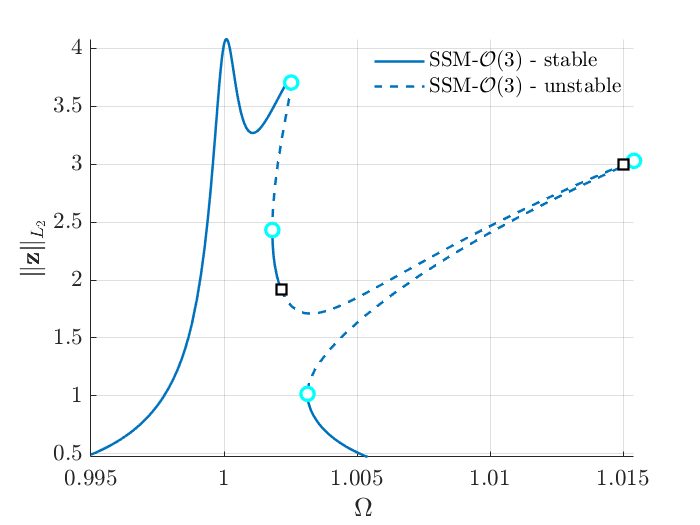

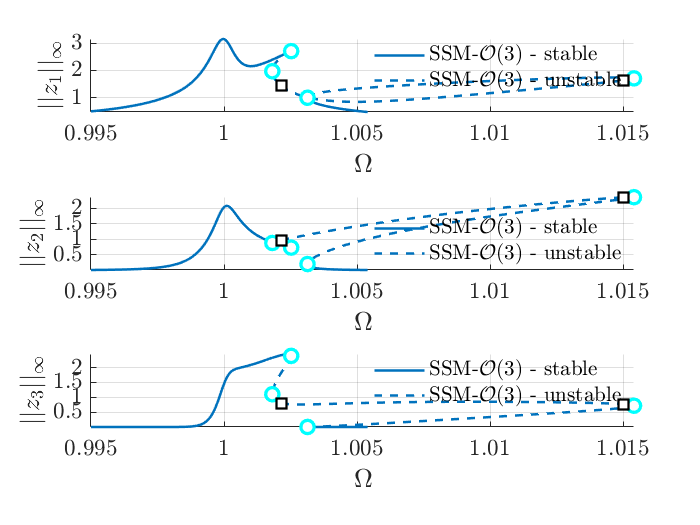

Total time spent on FRC computation upto O(3) = 00:00:12


set(S.Options, 'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'method','continuation ep')
set(S.FRCOptions, 'outdof',outdof)
set(S.FRCOptions, 'initialSolver', 'fsolve');
set(S.contOptions,'PtMX',250);

freqRange = [0.995 1.016];
% call extract_FRC to calculate the FRC
FRC = S.extract_FRC('freq',freqRange,order);

On the other hand, we can use SSM-ep toolbox to obtaint the FRC with a single continuation run as well given $\Omega\approx1$ in the whole frequency span. The SSM-ep toolbox is the minic of the ep-toolbox of COCO. It is in the middle level of the SSMTool while the extract_FRC routine is in the high level of the SSMTool. The continuation-based method implemented in the extract_FRC routine is actually built on the SSM-ep toolbox. Users may use the extract_FRC routine initially. They may explore the SSM-ep toolbox given this toolbox has more functionalities, e.g., bifurcation analysis.

We call the function SSM_isol2ep, whose arguments can be found via help

help SSM_isol2ep

--- help for SSM/SSM_isol2ep ---

  SSM_isol2ep This function performs continuation of equilibrium points of
  slow dynamics. Each equilibirum point corresponds to a periodic orbit in
  the regular time dynamics. The continuation here starts from the guess of
  initial solution.
 
  FRC = SSM_isol2ep(OBJ,OID,RESONANT_MODES,ORDER,MFREQS,PARNAME,PARRANGE,OUTDOF,VARARGIN)
 
  oid:      runid of continuation
  resonant_modes:    master subspace
  order:    expansion order of SSM
  mFreqs:   internal resonance relation vector
  parName:  amp/freq continuation parameter
  parRange: continuation domain of parameter, which should be near the
            value of natural frequency with index 1 in the mFreq if the continuation
            parameter is freq
  outdof:   output for dof in physical domain
  varargin: [{p0,z0}], ['saveICs'] where {p0,z0} are initial solution
            guesses and saveICs is a flag saving a point on trajectory as in

In this example, the resonant_modes should be [1 2 3 4 5 6] due to all modes are involved in the resonance. We have $\omega_1=\omega_2=\omega_3\approx\Omega$ and then $\mathbf{r}=[1,1,1]$ (mfreqs).  The argument parName can be amp or freq. When parName='freq'/'amp', the forced response curve with varied excitation frequency $\Omega$ / excitation amplitude $\epsilon$ is obtained.

sigma_out = 0
(near) inner resonance detected for the following combination of master eigenvalues
  Columns 1 through 5

     1     0     0     0     1
     0     0     0     0     2
     0     0     0     1     2
     0     0     1     0     1
     0     0     1     1     1
     0     0     2     0     0
     0     0     2     1     0
     0     1     0     0     2
     0     1     1     0     1
     0     1     2     0     0
     1     0     0     0     1
     1     0     0     1     1
     1     0     1     0     0
     1     0     1     1     0
     1     1     0     0     1
     1     1     1     0     0
     2     0     0     0     0
     2     0     0     1     0
     2     1     0     0     0
     0     1     0     0     0
     0     0     0     0     1
     0     0     0     1     1
     0     0     0     2     1
     0     0     1     0     0
     0     0     1     1     0
     0     0     1     2     0
     0     1     0     0     1
     0     1     0     1     1
     0     

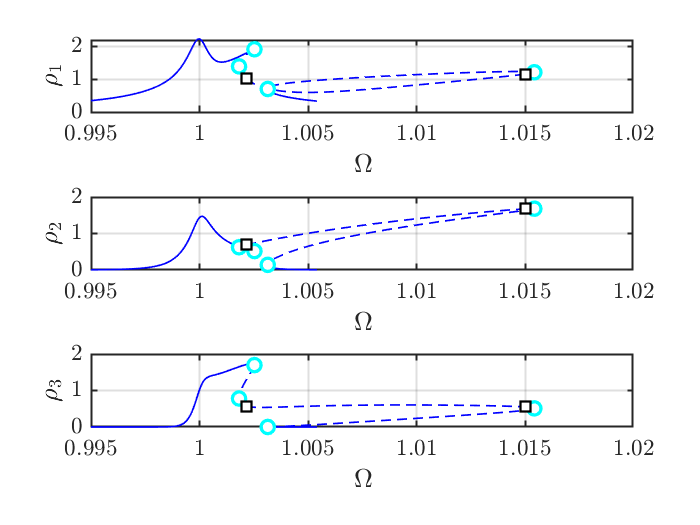

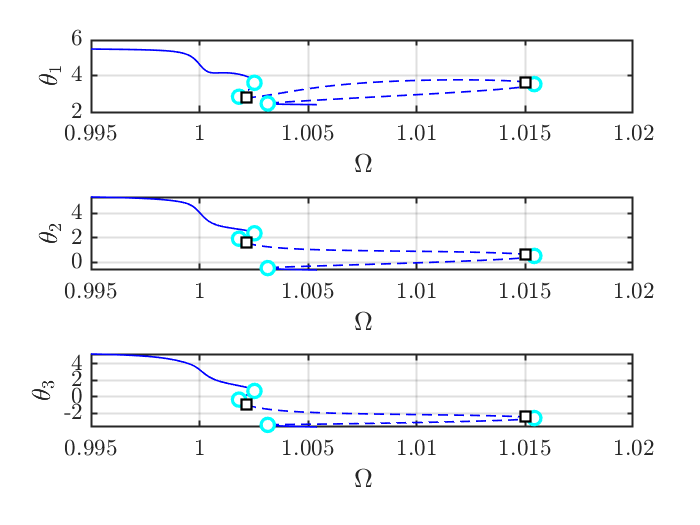

the forcing frequency 9.9500e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9501e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9515e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9529e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9543e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9557e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9585e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9598e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9611e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9636e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequenc

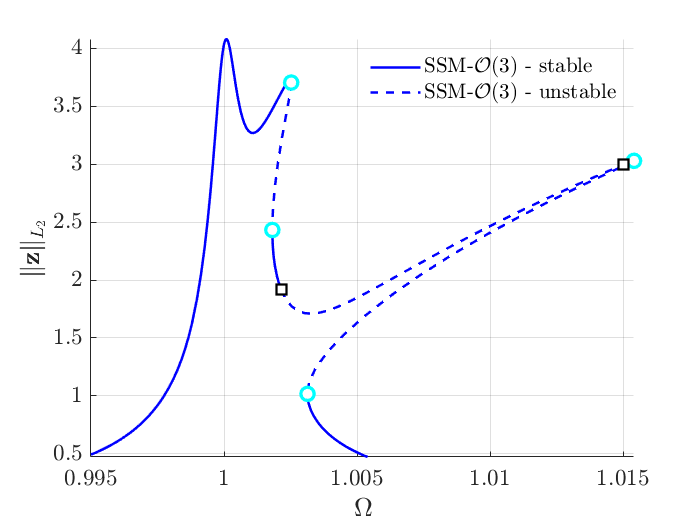

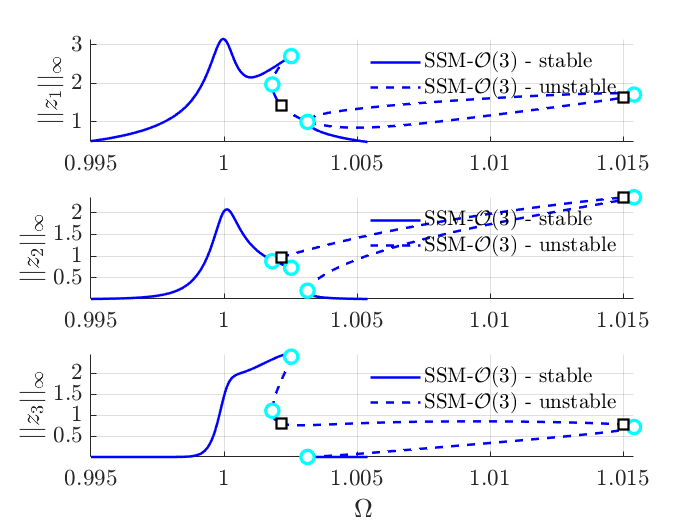

resonant_modes = [1 2 3 4 5 6];
mFreq  = [1 1 1];
set(S.contOptions,'PtMX',250);
startep = tic;
FRC_ep_polar = S.SSM_isol2ep('isol_polar',resonant_modes, order, mFreq, 'freq', freqRange, outdof);

timings.epPolarFRC = toc(startep);

As seen in the continuation hisotry, the continuation run terminated at a point where $\rho_3\to0$ (denoted as MX point), which triggers the singularity of the vector field. As an alternative, we can use Cartesian coordinates to remove the MX point.

sigma_out = 0
(near) inner resonance detected for the following combination of master eigenvalues
  Columns 1 through 5

     1     0     0     0     1
     0     0     0     0     2
     0     0     0     1     2
     0     0     1     0     1
     0     0     1     1     1
     0     0     2     0     0
     0     0     2     1     0
     0     1     0     0     2
     0     1     1     0     1
     0     1     2     0     0
     1     0     0     0     1
     1     0     0     1     1
     1     0     1     0     0
     1     0     1     1     0
     1     1     0     0     1
     1     1     1     0     0
     2     0     0     0     0
     2     0     0     1     0
     2     1     0     0     0
     0     1     0     0     0
     0     0     0     0     1
     0     0     0     1     1
     0     0     0     2     1
     0     0     1     0     0
     0     0     1     1     0
     0     0     1     2     0
     0     1     0     0     1
     0     1     0     1     1
     0     

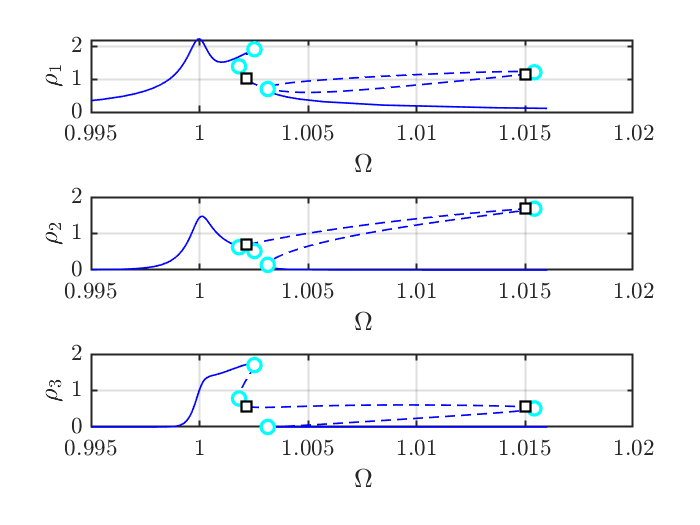

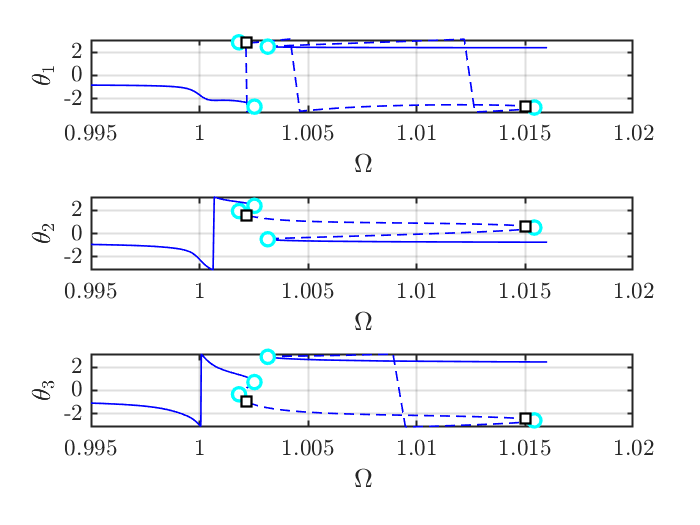

the forcing frequency 9.9500e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9555e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9645e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9704e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9751e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9789e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9823e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9850e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9871e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequency 9.9887e-01 is nearly resonant with the eigenvalue -2.5000e-04 + i1.0000e+00
the forcing frequenc

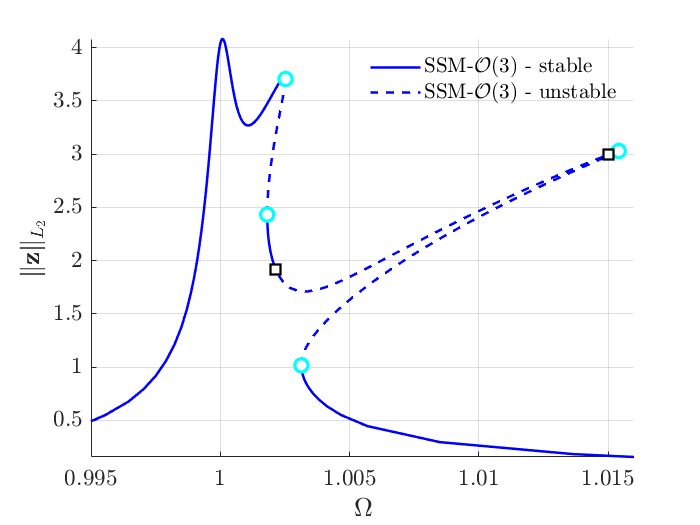

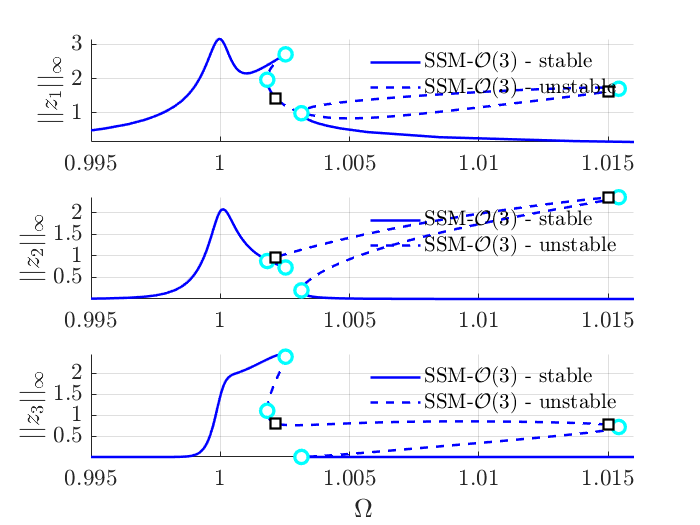

set(S.FRCOptions, 'coordinates','cartesian');
startep = tic;
FRC_ep_cart = S.SSM_isol2ep('isol_cart',resonant_modes, order, mFreq, 'freq', freqRange, outdof);

timings.epCartFRC = toc(startep);

## Validation using COCO

To conclude this example, we use the po-toolbox (collocation method) of COCO to validate the results obtained from the SSM analysis. As we can see, the results of the two methods match well. In addition, the runtime of collocation method is nearly three times of that of the SSM analysis.


 Run='FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.00e-02  1.06e+01    0.0    0.0    0.0
   1   1  1.00e+00  5.51e-01  3.11e-04  1.06e+01    0.0    0.0    0.0
   2   1  1.00e+00  3.28e-01  5.04e-06  1.06e+01    0.0    0.0    0.0
   3   1  1.00e+00  2.39e-03  8.14e-10  1.06e+01    0.0    0.0    0.0
   4   1  1.00e+00  7.35e-07  1.81e-15  1.06e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2         amp3
    0  00:00:00   1.0562e+01      1  EP      9.9697e-01   6.3023e+00   5.0000e-03   7.7455e-01   4.7293e-02   1.2789e-05
    5  00:00:00   9.8080e+00      2  EP      9.9500e-01   6.3148e+00   5.0000e-03   4.9155e-01   8.4633e-03   4.5087e-08

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps      

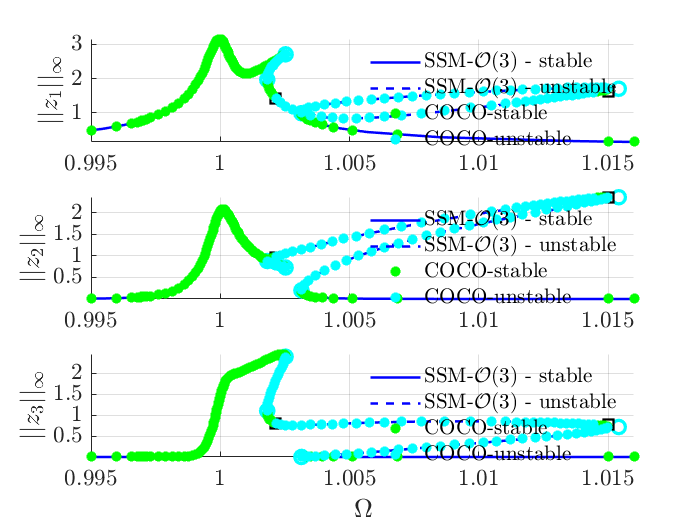

nCycles = 100;
coco = cocoWrapper(DS, nCycles, outdof);
set(coco.Options, 'PtMX', 500);
set(coco.Options, 'NAdapt', 1, 'h_max', 50);

startcoco = tic;
bd2 = coco.extract_FRC(freqRange);

timings.cocoFRC = toc(startcoco)

timings = struct with fields:
            MD: 0.0393
    epPolarFRC: 10.0970
     epCartFRC: 7.8357
       cocoFRC: 24.7929
